# Solving Richards Equation with Newton's Method

clear, close all, clc

Consider a horizontal column filled with soil so that infiltration is driven only by capillary diffusion

PDE: $\frac{\partial \theta}{\partial t} 
+ \nabla\cdot\left[D(\theta) \nabla\theta\right] = 0$

IC: $\theta(x,t=0) = \theta_0$

BC: $\theta(x=0,t) = \theta_b$

For simplicity we will consider the Brooks-Corey (BC) hydraulic diffusivity


$$D(\theta) = \frac{K_s h_b}{\lambda \Delta \theta}\left(\frac{\theta-\theta_r}{\Delta\theta}\right)^{2+\frac{1}{\lambda}}$$


$\Delta\theta = \theta_s-\theta_r$ and we use the values for silty loam from above. Due to the dependence of the hydraulic diffusivity on the water content this problem is non-linear. 

## Solution with Newton's Method

For the fully coupled solution we dicretize the PDE and evaluate all $\theta$'s at the new time level, `n+1`. The residual of the discretized equation is given by

`res`` = ``theta`` - ``theta_old`` - dt*(``D``*``Kd``(``theta``)*``G``)*``theta`` - dt*``fs`

where `theta`` = `$\theta^{n+1}$ and `theta_old`` =` $\theta^n$. The diagonal matrix **Kd** contains $D_h(\theta)$ averaged to the call faces with an arithmetic average.

This residual is non-linear and hence cannot be written as a liner system in the form 

**L*****theta** $\neq$ dt***fs** .

We must use Netwon's method and linearize the residual

$\mathbf{r}(\mathbf{\theta}^{k+1}) \approx \mathbf{r}(\mathbf{\theta}^k) + \nabla\mathbf{r}(\mathbf{\theta}^k)\,\Delta\mathbf{\theta}^k=0$,

and iterate by finding the roots of successive residuals, $k$, for the update vector, $\Delta \theta$.

### Determining the Jacobian Matrix

The Jacobian matrix $\mathbf{J} = \nabla\mathbf{r}(\mathbf{\theta}^k)$ can be determined by computing the directional derivative, $D_{\hat{\mathbf{\theta}}}\mathbf{r}(\overline{\mathbf{\theta}}) = \mathbf{J}(\overline{\mathbf{\theta}})  \, \hat{\mathbf{\theta}}$, of the residual at $\overline{\theta}=\theta^k$ in the direction of the update $\hat{\theta} = \Delta \theta^k/\epsilon$ as follows

$D_{\hat{\mathbf{\theta}}}\mathbf{r}(\overline{\mathbf{\theta}}) = \frac{\mathrm{d}}{\mathrm{d}\epsilon}\left.\mathbf{r}\left(\overline{\mathbf{\theta}}+\epsilon\, \hat{\mathbf{\theta}}\right)\right|_{\epsilon=0} = \frac{\mathrm{d}}{\mathrm{d}\epsilon}\left.\overline{\mathbf{\theta}}+\epsilon\,\hat{\mathbf{\theta}}-\mathbf{\theta}^n-\Delta t \,\mathbf{D}\left[\mathbf{Kd}(\overline{\mathbf{\theta}}+\epsilon\,\hat{\mathbf{\theta}})\,\mathbf{G}(\overline{\mathbf{\theta}}+\epsilon\,\hat{\mathbf{\theta}})\right] \right|_{\epsilon=0}$.

computing this derivative (see class notes for details) we obtain the Jacobian as

$\mathbf{$`J``(``theta``) = ``I`` - ``dt``*``D``*(``GU``*``dKd`` + ``Kd``*``G``)`

where the matrices are given by

`GU`` = spdiags(``G``*``theta``,0,Nf,Nf)`

`Kd`` = spdiags(``M``*DH(``theta``),0,Nf,Nf)`

`dKd`` = spdiags(``M``*dDH(``theta``),0,Nf,Nf).`

Here the hydraulic diffusivity is `DH` and its derivative `dDH`, the latter is given by


$$\frac{\mathrm{d} D_H}{\mathrm{d}\theta} = \frac{K_s h_b}{\Delta\theta^2} \frac{1+2\lambda}{\lambda^2} \left(\frac{\theta-\theta_r}{\Delta \theta}\right)^{1+\frac{1}{\lambda}}$$


for the Brooks-Corey constitutive function. Hence the Jacobian can easili be evaluated analytically from our discrete operators. This generally speeds up the evaluation of the Jacobian significantly and is also avoids errors due to the finite difference approximation.

## Numerical solution with Newtons Method

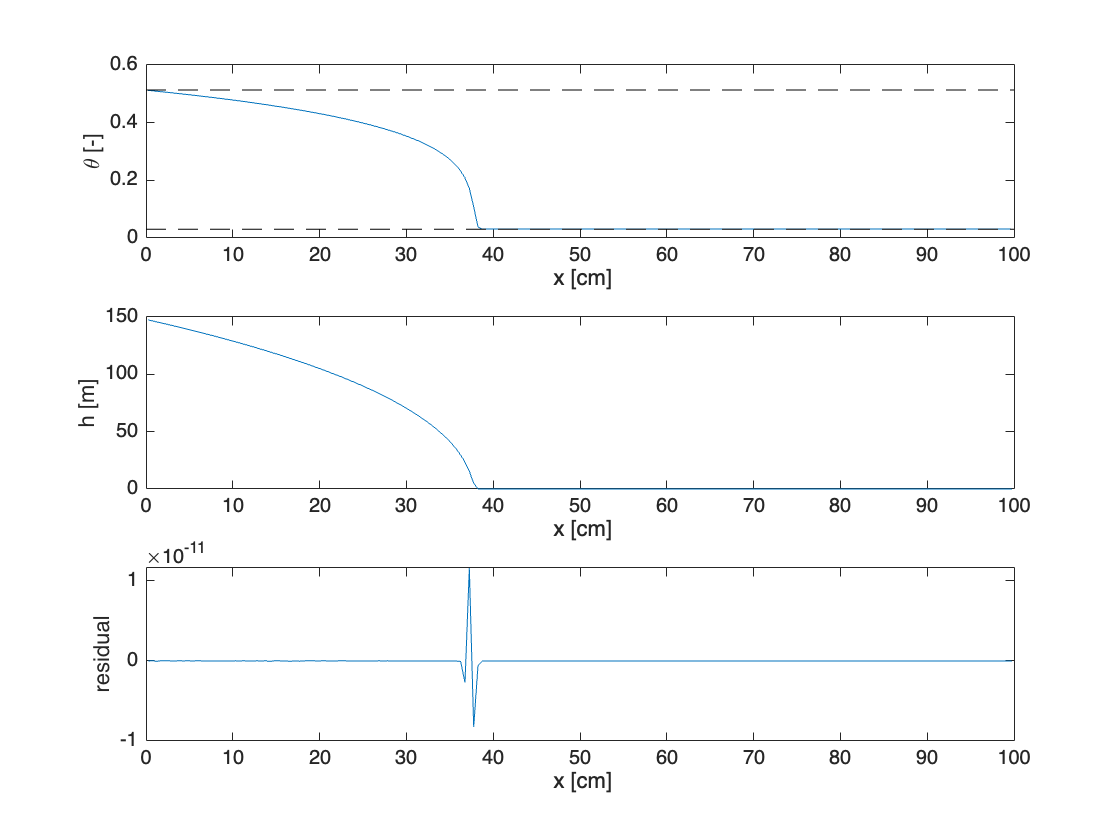

it = 1: nres = 7.43e+01  ndtheta = 4.77e-01
it = 2: nres = 7.09e+01  ndtheta = 4.72e-01
it = 3: nres = 6.05e+01  ndtheta = 4.59e-01
it = 4: nres = 6.81e+01  ndtheta = 4.66e-01
it = 5: nres = 2.52e+01  ndtheta = 3.92e-01
it = 6: nres = 2.50e+02  ndtheta = 5.90e-01
it = 7: nres = 7.73e+01  ndtheta = 1.74e-01
it = 8: nres = 5.02e+01  ndtheta = 4.24e-01
it = 9: nres = 8.27e+00  ndtheta = 2.60e-01
it = 10: nres = 8.18e+01  ndtheta = 4.69e-01
it = 11: nres = 2.57e+01  ndtheta = 1.23e-01
it = 12: nres = 7.99e+00  ndtheta = 1.05e-01
it = 13: nres = 2.34e+00  ndtheta = 9.68e-02
it = 14: nres = 5.08e-01  ndtheta = 6.57e-02
it = 15: nres = 4.73e-02  ndtheta = 1.63e-02
it = 16: nres = 4.50e-04  ndtheta = 1.53e-03
it = 17: nres = 4.25e-08  ndtheta = 1.50e-05
it = 18: nres = 4.36e-14  ndtheta = 1.39e-09


Newton converged after 18 iterations.



it = 1: nres = 1.48e+02  ndtheta = 7.66e-01
it = 2: nres = 4.83e+01  ndtheta = 2.01e-01
it = 3: nres = 1.56e+01  ndtheta = 2.08e-01
it = 4: nres = 4.63e+00  ndtheta = 1.25e-01
it = 5: nres = 9.47e-01  ndtheta = 5.42e-02
it = 6: nres = 6.73e-02  ndtheta = 1.41e-02
it = 7: nres = 3.82e-04  ndtheta = 1.07e-03
it = 8: nres = 1.24e-08  ndtheta = 5.81e-06
it = 9: nres = 6.17e-14  ndtheta = 1.93e-10


Newton converged after 9 iterations.



it = 1: nres = 5.18e+01  ndtheta = 5.75e-01
it = 2: nres = 1.67e+01  ndtheta = 1.25e-01
it = 3: nres = 5.12e+00  ndtheta = 1.12e-01
it = 4: nres = 1.60e+00  ndtheta = 1.37e-01
it = 5: nres = 2.86e-01  ndtheta = 7.11e-02
it = 6: nres = 2.13e-02  ndtheta = 1.83e-02
it = 7: nres = 1.10e-04  ndtheta = 1.30e-03
it = 8: nres = 2.43e-09  ndtheta = 5.09e-06
it = 9: nres = 5.72e-14  ndtheta = 1.64e-10


Newton converged after 9 iterations.



it = 1: nres = 1.80e+01  ndtheta = 4.47e-01
it = 2: nres = 5.84e+00  ndtheta = 1.45e-01
it = 3: nres = 1.75e+00  ndtheta = 9.00e-02
it = 4: nres = 3.40e-01  ndtheta = 3.31e-02
it = 5: nres = 2.14e-02  ndtheta = 1.02e-02
it = 6: nres = 9.49e-05  ndtheta = 6.82e-04
it = 7: nres = 1.87e-09  ndtheta = 3.03e-06
it = 8: nres = 1.23e-13  ndtheta = 5.95e-11


Newton converged after 8 iterations.



it = 1: nres = 1.12e+01  ndtheta = 3.86e-01
it = 2: nres = 3.61e+00  ndtheta = 1.24e-01
it = 3: nres = 1.02e+00  ndtheta = 6.14e-02
it = 4: nres = 1.73e-01  ndtheta = 2.88e-02
it = 5: nres = 7.59e-03  ndtheta = 6.72e-03
it = 6: nres = 1.56e-05  ndtheta = 2.97e-04
it = 7: nres = 6.64e-11  ndtheta = 6.22e-07


Newton converged after 7 iterations.



it = 1: nres = 1.11e+01  ndtheta = 3.61e-01
it = 2: nres = 3.51e+00  ndtheta = 8.53e-02
it = 3: nres = 1.03e+00  ndtheta = 7.49e-02
it = 4: nres = 2.38e-01  ndtheta = 4.94e-02
it = 5: nres = 2.18e-02  ndtheta = 1.38e-02
it = 6: nres = 2.25e-04  ndtheta = 1.37e-03
it = 7: nres = 2.23e-08  ndtheta = 1.36e-05
it = 8: nres = 6.85e-14  ndtheta = 1.36e-09


Newton converged after 8 iterations.



it = 1: nres = 4.89e+00  ndtheta = 3.11e-01
it = 2: nres = 1.55e+00  ndtheta = 9.91e-02
it = 3: nres = 3.80e-01  ndtheta = 4.02e-02
it = 4: nres = 4.12e-02  ndtheta = 1.60e-02
it = 5: nres = 6.33e-04  ndtheta = 2.16e-03
it = 6: nres = 1.51e-07  ndtheta = 3.32e-05
it = 7: nres = 8.73e-14  ndtheta = 7.96e-09


Newton converged after 7 iterations.



it = 1: nres = 2.13e+00  ndtheta = 2.93e-01
it = 2: nres = 6.21e-01  ndtheta = 9.51e-02
it = 3: nres = 1.15e-01  ndtheta = 4.12e-02
it = 4: nres = 5.33e-03  ndtheta = 1.01e-02
it = 5: nres = 1.12e-05  ndtheta = 3.59e-04
it = 6: nres = 5.19e-11  ndtheta = 7.27e-07


Newton converged after 6 iterations.



it = 1: nres = 1.64e+00  ndtheta = 2.75e-01
it = 2: nres = 4.56e-01  ndtheta = 8.65e-02
it = 3: nres = 7.48e-02  ndtheta = 3.87e-02
it = 4: nres = 4.01e-03  ndtheta = 1.10e-02
it = 5: nres = 1.72e-05  ndtheta = 5.35e-04
it = 6: nres = 3.68e-10  ndtheta = 2.44e-06
it = 7: nres = 8.51e-14  ndtheta = 4.18e-11


Newton converged after 7 iterations.



it = 1: nres = 1.38e+00  ndtheta = 2.55e-01
it = 2: nres = 3.87e-01  ndtheta = 8.16e-02
it = 3: nres = 5.77e-02  ndtheta = 3.00e-02
it = 4: nres = 1.64e-03  ndtheta = 5.51e-03
it = 5: nres = 1.27e-06  ndtheta = 1.12e-04
it = 6: nres = 7.25e-13  ndtheta = 8.11e-08


Newton converged after 6 iterations.



it = 1: nres = 1.76e+00  ndtheta = 2.36e-01
it = 2: nres = 5.24e-01  ndtheta = 7.00e-02
it = 3: nres = 9.23e-02  ndtheta = 2.37e-02
it = 4: nres = 4.23e-03  ndtheta = 5.97e-03
it = 5: nres = 1.02e-05  ndtheta = 3.05e-04
it = 6: nres = 5.86e-11  ndtheta = 7.26e-07


Newton converged after 6 iterations.



it = 1: nres = 2.38e+00  ndtheta = 2.28e-01
it = 2: nres = 7.17e-01  ndtheta = 5.39e-02
it = 3: nres = 1.69e-01  ndtheta = 3.85e-02
it = 4: nres = 1.77e-02  ndtheta = 1.41e-02
it = 5: nres = 2.42e-04  ndtheta = 1.67e-03
it = 6: nres = 4.59e-08  ndtheta = 2.30e-05
it = 7: nres = 1.03e-13  ndtheta = 4.35e-09


Newton converged after 7 iterations.



it = 1: nres = 1.40e+00  ndtheta = 2.26e-01
it = 2: nres = 4.07e-01  ndtheta = 6.49e-02
it = 3: nres = 9.02e-02  ndtheta = 3.42e-02
it = 4: nres = 9.01e-03  ndtheta = 1.21e-02
it = 5: nres = 9.47e-05  ndtheta = 1.17e-03
it = 6: nres = 1.12e-08  ndtheta = 1.33e-05
it = 7: nres = 1.08e-13  ndtheta = 1.49e-09


Newton converged after 7 iterations.



it = 1: nres = 1.05e+00  ndtheta = 2.04e-01
it = 2: nres = 2.95e-01  ndtheta = 5.71e-02
it = 3: nres = 4.00e-02  ndtheta = 1.72e-02
it = 4: nres = 1.01e-03  ndtheta = 3.17e-03
it = 5: nres = 7.00e-07  ndtheta = 8.53e-05
it = 6: nres = 3.57e-13  ndtheta = 5.84e-08


Newton converged after 6 iterations.



it = 1: nres = 1.49e+00  ndtheta = 2.06e-01
it = 2: nres = 4.40e-01  ndtheta = 5.63e-02
it = 3: nres = 9.82e-02  ndtheta = 3.20e-02
it = 4: nres = 9.54e-03  ndtheta = 1.18e-02
it = 5: nres = 1.02e-04  ndtheta = 1.20e-03
it = 6: nres = 1.22e-08  ndtheta = 1.37e-05
it = 7: nres = 1.05e-13  ndtheta = 1.59e-09


Newton converged after 7 iterations.



it = 1: nres = 7.49e-01  ndtheta = 1.89e-01
it = 2: nres = 1.98e-01  ndtheta = 5.21e-02
it = 3: nres = 2.16e-02  ndtheta = 1.35e-02
it = 4: nres = 3.13e-04  ndtheta = 1.80e-03
it = 5: nres = 7.38e-08  ndtheta = 2.89e-05
it = 6: nres = 9.79e-14  ndtheta = 6.49e-09


Newton converged after 6 iterations.



it = 1: nres = 1.03e+00  ndtheta = 1.92e-01
it = 2: nres = 2.96e-01  ndtheta = 5.40e-02
it = 3: nres = 6.07e-02  ndtheta = 2.79e-02
it = 4: nres = 4.60e-03  ndtheta = 8.53e-03
it = 5: nres = 2.88e-05  ndtheta = 6.77e-04
it = 6: nres = 1.17e-09  ndtheta = 4.41e-06
it = 7: nres = 9.29e-14  ndtheta = 1.76e-10


Newton converged after 7 iterations.



it = 1: nres = 8.54e-01  ndtheta = 1.74e-01
it = 2: nres = 2.31e-01  ndtheta = 3.90e-02
it = 3: nres = 3.27e-02  ndtheta = 1.80e-02
it = 4: nres = 9.78e-04  ndtheta = 3.63e-03
it = 5: nres = 8.92e-07  ndtheta = 1.07e-04
it = 6: nres = 7.71e-13  ndtheta = 1.01e-07


Newton converged after 6 iterations.



it = 1: nres = 3.95e-01  ndtheta = 1.76e-01
it = 2: nres = 8.41e-02  ndtheta = 5.05e-02
it = 3: nres = 7.12e-03  ndtheta = 1.58e-02
it = 4: nres = 1.15e-04  ndtheta = 1.69e-03
it = 5: nres = 2.82e-08  ndtheta = 2.46e-05
it = 6: nres = 1.21e-13  ndtheta = 5.89e-09


Newton converged after 6 iterations.



it = 1: nres = 8.59e-01  ndtheta = 1.72e-01
it = 2: nres = 2.43e-01  ndtheta = 4.74e-02
it = 3: nres = 4.56e-02  ndtheta = 2.40e-02
it = 4: nres = 2.73e-03  ndtheta = 6.59e-03
it = 5: nres = 1.06e-05  ndtheta = 4.15e-04
it = 6: nres = 1.63e-10  ndtheta = 1.65e-06
it = 7: nres = 1.01e-13  ndtheta = 2.51e-11


Newton converged after 7 iterations.



it = 1: nres = 6.73e-01  ndtheta = 1.59e-01
it = 2: nres = 1.75e-01  ndtheta = 3.45e-02
it = 3: nres = 2.30e-02  ndtheta = 1.61e-02
it = 4: nres = 5.60e-04  ndtheta = 2.83e-03
it = 5: nres = 3.42e-07  ndtheta = 6.98e-05
it = 6: nres = 1.68e-13  ndtheta = 4.32e-08


Newton converged after 6 iterations.



it = 1: nres = 3.44e-01  ndtheta = 1.58e-01
it = 2: nres = 7.30e-02  ndtheta = 4.08e-02
it = 3: nres = 4.13e-03  ndtheta = 7.65e-03
it = 4: nres = 1.37e-05  ndtheta = 3.89e-04
it = 5: nres = 1.66e-10  ndtheta = 1.46e-06
it = 6: nres = 1.07e-13  ndtheta = 1.72e-11


Newton converged after 6 iterations.



it = 1: nres = 3.62e-01  ndtheta = 1.60e-01
it = 2: nres = 8.69e-02  ndtheta = 4.46e-02
it = 3: nres = 1.15e-02  ndtheta = 1.64e-02
it = 4: nres = 2.75e-04  ndtheta = 2.44e-03
it = 5: nres = 1.58e-07  ndtheta = 5.86e-05
it = 6: nres = 1.27e-13  ndtheta = 3.36e-08


Newton converged after 6 iterations.



it = 1: nres = 5.88e-01  ndtheta = 1.55e-01
it = 2: nres = 1.60e-01  ndtheta = 4.28e-02
it = 3: nres = 2.61e-02  ndtheta = 1.99e-02
it = 4: nres = 1.08e-03  ndtheta = 4.35e-03
it = 5: nres = 1.96e-06  ndtheta = 1.89e-04
it = 6: nres = 6.57e-12  ndtheta = 3.47e-07


Newton converged after 6 iterations.



it = 1: nres = 5.76e-01  ndtheta = 1.46e-01
it = 2: nres = 1.50e-01  ndtheta = 3.64e-02
it = 3: nres = 2.14e-02  ndtheta = 1.67e-02
it = 4: nres = 6.29e-04  ndtheta = 3.18e-03
it = 5: nres = 5.66e-07  ndtheta = 9.63e-05
it = 6: nres = 4.81e-13  ndtheta = 8.76e-08


Newton converged after 6 iterations.



it = 1: nres = 4.41e-01  ndtheta = 1.39e-01
it = 2: nres = 1.05e-01  ndtheta = 2.90e-02
it = 3: nres = 1.04e-02  ndtheta = 1.15e-02
it = 4: nres = 1.36e-04  ndtheta = 1.45e-03
it = 5: nres = 2.30e-08  ndtheta = 1.88e-05
it = 6: nres = 1.56e-13  ndtheta = 3.23e-09


Newton converged after 6 iterations.



it = 1: nres = 3.13e-01  ndtheta = 1.37e-01
it = 2: nres = 6.65e-02  ndtheta = 2.85e-02
it = 3: nres = 3.93e-03  ndtheta = 6.76e-03
it = 4: nres = 1.80e-05  ndtheta = 5.26e-04
it = 5: nres = 3.59e-10  ndtheta = 2.27e-06
it = 6: nres = 1.34e-13  ndtheta = 4.71e-11


Newton converged after 6 iterations.



it = 1: nres = 2.21e-01  ndtheta = 1.36e-01
it = 2: nres = 4.01e-02  ndtheta = 3.14e-02
it = 3: nres = 1.49e-03  ndtheta = 4.57e-03
it = 4: nres = 2.10e-06  ndtheta = 1.64e-04
it = 5: nres = 4.80e-12  ndtheta = 2.67e-07


Newton converged after 5 iterations.



it = 1: nres = 1.74e-01  ndtheta = 1.36e-01
it = 2: nres = 2.64e-02  ndtheta = 3.36e-02
it = 3: nres = 6.40e-04  ndtheta = 6.07e-03
it = 4: nres = 6.79e-07  ndtheta = 1.88e-04
it = 5: nres = 1.45e-12  ndtheta = 2.27e-07


Newton converged after 5 iterations.



it = 1: nres = 1.73e-01  ndtheta = 1.35e-01
it = 2: nres = 2.95e-02  ndtheta = 3.46e-02
it = 3: nres = 1.83e-03  ndtheta = 8.39e-03
it = 4: nres = 9.63e-06  ndtheta = 5.44e-04
it = 5: nres = 2.47e-10  ndtheta = 2.73e-06
it = 6: nres = 1.47e-13  ndtheta = 7.01e-11


Newton converged after 6 iterations.



it = 1: nres = 1.89e-01  ndtheta = 1.33e-01
it = 2: nres = 3.81e-02  ndtheta = 3.48e-02
it = 3: nres = 3.22e-03  ndtheta = 9.95e-03
it = 4: nres = 2.70e-05  ndtheta = 8.76e-04
it = 5: nres = 1.86e-09  ndtheta = 7.29e-06
it = 6: nres = 1.43e-13  ndtheta = 5.04e-10


Newton converged after 6 iterations.



it = 1: nres = 2.02e-01  ndtheta = 1.31e-01
it = 2: nres = 4.37e-02  ndtheta = 3.46e-02
it = 3: nres = 4.06e-03  ndtheta = 1.07e-02
it = 4: nres = 4.11e-05  ndtheta = 1.06e-03
it = 5: nres = 4.26e-09  ndtheta = 1.09e-05
it = 6: nres = 1.29e-13  ndtheta = 1.13e-09


Newton converged after 6 iterations.



it = 1: nres = 2.04e-01  ndtheta = 1.29e-01
it = 2: nres = 4.50e-02  ndtheta = 3.41e-02
it = 3: nres = 4.24e-03  ndtheta = 1.08e-02
it = 4: nres = 4.45e-05  ndtheta = 1.11e-03
it = 5: nres = 4.98e-09  ndtheta = 1.17e-05
it = 6: nres = 1.58e-13  ndtheta = 1.31e-09


Newton converged after 6 iterations.



it = 1: nres = 1.95e-01  ndtheta = 1.27e-01
it = 2: nres = 4.26e-02  ndtheta = 3.33e-02
it = 3: nres = 3.87e-03  ndtheta = 1.04e-02
it = 4: nres = 3.76e-05  ndtheta = 1.03e-03
it = 5: nres = 3.60e-09  ndtheta = 1.01e-05
it = 6: nres = 1.19e-13  ndtheta = 9.65e-10


Newton converged after 6 iterations.



it = 1: nres = 1.76e-01  ndtheta = 1.24e-01
it = 2: nres = 3.71e-02  ndtheta = 3.23e-02
it = 3: nres = 3.11e-03  ndtheta = 9.55e-03
it = 4: nres = 2.51e-05  ndtheta = 8.57e-04
it = 5: nres = 1.65e-09  ndtheta = 6.97e-06
it = 6: nres = 1.25e-13  ndtheta = 4.58e-10


Newton converged after 6 iterations.



it = 1: nres = 1.51e-01  ndtheta = 1.22e-01
it = 2: nres = 2.94e-02  ndtheta = 3.10e-02
it = 3: nres = 2.14e-03  ndtheta = 8.29e-03
it = 4: nres = 1.24e-05  ndtheta = 6.24e-04
it = 5: nres = 4.21e-10  ndtheta = 3.64e-06
it = 6: nres = 1.67e-13  ndtheta = 1.24e-10


Newton converged after 6 iterations.



it = 1: nres = 1.25e-01  ndtheta = 1.20e-01
it = 2: nres = 2.07e-02  ndtheta = 2.92e-02
it = 3: nres = 1.15e-03  ndtheta = 6.60e-03
it = 4: nres = 3.88e-06  ndtheta = 3.65e-04
it = 5: nres = 4.33e-11  ndtheta = 1.22e-06
it = 6: nres = 1.37e-13  ndtheta = 1.37e-11


Newton converged after 6 iterations.



it = 1: nres = 1.06e-01  ndtheta = 1.17e-01
it = 2: nres = 1.34e-02  ndtheta = 2.68e-02
it = 3: nres = 3.92e-04  ndtheta = 4.55e-03
it = 4: nres = 5.14e-07  ndtheta = 1.44e-04
it = 5: nres = 8.24e-13  ndtheta = 1.77e-07


Newton converged after 5 iterations.



it = 1: nres = 1.03e-01  ndtheta = 1.13e-01
it = 2: nres = 1.19e-02  ndtheta = 2.37e-02
it = 3: nres = 1.43e-04  ndtheta = 2.61e-03
it = 4: nres = 2.40e-08  ndtheta = 2.74e-05
it = 5: nres = 1.26e-13  ndtheta = 3.21e-09


Newton converged after 5 iterations.



it = 1: nres = 1.18e-01  ndtheta = 1.10e-01
it = 2: nres = 1.63e-02  ndtheta = 2.01e-02
it = 3: nres = 3.06e-04  ndtheta = 2.05e-03
it = 4: nres = 1.20e-07  ndtheta = 4.33e-05
it = 5: nres = 1.43e-13  ndtheta = 1.81e-08


Newton converged after 5 iterations.



it = 1: nres = 1.43e-01  ndtheta = 1.06e-01
it = 2

% Rock properties (silt loam - Brooks Corey)
rock.Ks = 30.5; % [cm/d]
rock.theta_s = 0.513;
rock.lambda = 0.54;
rock.theta_r = 0.03;
rock.hb = 1.48*100; % [cm]

% Constitutive functions
sat = @(theta,rock) (theta-rock.theta_r)/(rock.theta_s-rock.theta_r);
DBC = @(theta,rock) rock.Ks*rock.hb/(rock.lambda*(rock.theta_s-rock.theta_r))*sat(theta,rock).^(2+1/rock.lambda);
% Analytic Drivative of the Hydraulic Diffusivity 
dDBC = @(theta,rock) rock.Ks*rock.hb/(rock.theta_s-rock.theta_r)^2*(1+2*rock.lambda)/rock.lambda^2*sat(theta,rock).^(1+1/rock.lambda);

%% Build Grid and Operators
theta_0 = rock.theta_r+0.001;
theta_b = rock.theta_s-0.001;

Grid.xmin = 0; Grid.xmax = 100; Grid.Nx = 200;
Grid = build_grid(Grid);

% Build operatror
[D,G,~,I,M] = build_ops(Grid);
Kd = @(theta) comp_mean(DBC(theta,rock),M,1,Grid,1);
L = @(theta) -D*Kd(theta)*G;
IM = @(theta,dt) I + dt*L(theta);
EX = @(theta,dt) I ;
fs = spalloc(Grid.N,1,0);

% Build BC's
BC.dof_dir   = Grid.dof_xmin;
BC.dof_f_dir = Grid.dof_f_xmin;
BC.g = 0; % set BC in initial guess and then don't update bnd!
BC.dof_neu   = [];
BC.dof_f_neu = [];
BC.qb        = [];
[B,N,fn] = build_bnd(BC,Grid,I);

% IC
theta = theta_0*ones(Grid.N,1);
theta(BC.dof_dir) = theta_b;

%% Time integration
tmax = 1;
Nt = 3e2;
dt = tmax/Nt;

%% Newton iteration
tol = 1e-6; % convergence tolerance
kmax = 20;   % maximum number of iterations
epsilon = 1e-4;
figure
tic
for n = 1:Nt % timestepping loop
    theta_old = theta; 
    % Newton-Raphson Iteration
    nres = 1; ndtheta = 1; k = 0;
    while (nres > tol || ndtheta > tol) && k < kmax
        % Compute residual vector and Jacobian matrix
        res = comp_residual_richards(theta,theta_old,D,Kd,G,fs,dt,BC);
        Jac = comp_jacobian_richards_ana(theta,Grid,D,G,I,M,DBC,dDBC,dt,rock);
        
        % Solve for update and compute new iterate
        dtheta = solve_lbvp(Jac,-res,B,BC.g,N);
        theta = theta + dtheta;
        res = comp_residual_richards(theta,theta_old,D,Kd,G,fs,dt,BC);
        nres = norm(N'*res); ndtheta = norm(N'*dtheta);
        
        % Update convergence criteria
        k = k+1;
        fprintf('it = %d: nres = %3.2e  ndtheta = %3.2e\n',k,nres,ndtheta)
        if k == 1; ndtheta = 0; end % to allow exit on first iteration
    end
    if k<kmax+1; 
        fprintf('Newton converged after %d iterations.\n\n',k) 
    else
        fprintf('Newton did not converge\n\n') 
    end
    if mod(n,1) == 0
        subplot 311
        plot(Grid.xc,theta), hold on
        plot([0 100],rock.theta_r*[1 1],'k--')
        plot([0 100],rock.theta_s*[1 1],'k--')
        xlabel ' x [cm]'
        ylabel '\theta [-]'
        hold off
        
        subplot 312
        plot(Grid.xc,rock.hb*sat(theta,rock).^(1/rock.lambda)),
        xlabel ' x [cm]'
        ylabel 'h [m]'

        subplot 313
        plot(Grid.xc,res)
        xlabel ' x [cm]'
        ylabel 'residual'
        drawnow
    end
end


toc

## Auxillary functions

### Function that computes the residual

%% Residual Richards Equation (horizontal - no gravity)
function [res] = comp_residual_richards(theta,theta_old,D,Kd,G,fs,dt,BC)
    res = theta - theta_old - dt*(D*Kd(theta)*G)*theta - dt*fs;
    res(BC.dof_dir) = 0;
end

### Function that computes the Jacobian

%% Analytical Jacobian Richards Equation
function [Jac] = comp_jacobian_richards_ana(theta,Grid,D,G,I,M,Diff,dDiff,dt,rock)
GU = spdiags(G*theta,0,Grid.Nf,Grid.Nf); % Gradient on diagonal
Kd = comp_mean(Diff(theta,rock),M,1,Grid,1);
dKd = spdiags(dDiff(theta,rock),0,Grid.N, Grid.N);
Jac = I - dt*D*(GU*M*dKd + Kd*G);
end